**Parámetros Orbitales**

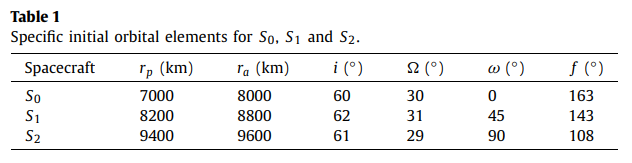

s0.rp = 7000;
s0.ra = 8000;
s0.a = (s0.rp + s0.ra) / 2;
s0.e = (s0.ra - s0.rp) / (s0.ra + s0.rp);
s0.i = deg2rad(60);
s0.Omega = deg2rad(30);
s0.omega = deg2rad(0);
s0.f = deg2rad(163);

s1.rp = 8200;
s1.ra = 8000;
s1.a = (s1.rp + s1.ra) / 2;
s1.e = (s1.ra - s1.rp) / (s1.ra + s1.rp);
s1.i = deg2rad(60);
s1.Omega = deg2rad(30);
s1.omega = deg2rad(45);
s1.f = deg2rad(143);

s2.rp = 9400;
s2.ra = 9600;
s2.a = (s2.rp + s2.ra) / 2;
s2.e = (s2.ra - s2.rp) / (s2.ra + s2.rp);
s2.i = deg2rad(61);
s2.Omega = deg2rad(29);
s2.omega = deg2rad(90);
s2.f = deg2rad(108);

orbitas = [s0.rp s0.ra s0.i s0.Omega s0.omega s0.f;
           s1.rp s1.ra s1.i s1.Omega s1.omega s1.f;
           s2.rp s2.ra s2.i s2.Omega s2.omega s2.f];

**a) Constantes iniciales (Tierra)**

earth_mu = 398600.4418 % parametro de gravedad (asumimos órbita en tierra)

earth_mu = 3.9860e+05

ti = 0 % tiempo inicial, 0 como ejemplo

ti = 0

**Variables Utilizadas**

Tenemos 3 objetos: $S_0$, $S_1$, $S_2$, los cuales son la nave perseguidora, el primer, y el segundo objeto, respectivamente.

También tenemos 4 tiempos: $t_i$ (tiempo inicial), $t_0$ (momento del impulso), $t_1$ (momento de interceptación con el 1er objeto), $t_2$ (interceptación con el 2do objeto).

Inicialmente, nuestros objetos se encuentran en las posiciones:

- 
$$S_{0, {t_i}}$$


- 
$$S_{1, {t_i}}$$


- 
$$S_{1, {t_i}}$$


Los vectores de posición correspondientes son:

- 
$$\textbf{r}_{0, {t_i}}$$


- 
$$\textbf{r}_{1, {t_i}}$$


- 
$$\textbf{r}_{2, {t_i}}$$


- Note el uso de $\textbf{r}$ en vez de $r$. Estos son parámetros completamente distintos, ejercer cuidado para no confundirlos.

Tenemos 4 órbitas, usadas como índices para los vectores que utilizaremos:

- 0: Órbita inicial de nuestro objeto $S_0$

- 1: Órbita del objeto a interceptar $S_1$

- 2. Órbita del objeto a interceptar $S_2$

- 3: Órbita de interceptación, a la que nuestro objeto $S_0$ cambia luego de aplicar el impulso $\triangle v$

Utilizamos estos índices para representar los vectores. de la siguiente forma:

- $v_{3, {t_2}}$: Vector de velocidad en la órbita de interceptación, en el momento en el que interceptamos al objeto 2

- $\textbf{r}_{1,{t_1}}$: Vector de posición del objeto 1 (y también de la nave perseguidora) en el momento en el que interceptamos al objeto 1

Los parámetros de las órbitas de $S_0$, $S_1$, $S_2$ se encuentran en la tabla 1.

**Modelo de dos cuerpos**

A partir de ahora, nos referiremos a la nave perseguidora como NP.

Si tenemos dos vectores que no son múltiplos o iguales, podemos determinar el plano al que pertenecen. En otras palabras, si tenemos los vectores:

- $\textbf{r}_{0, {t_0}}$: Posición de NP en el momento del impulso,

- $\textbf{r}_{1, {t_1}}$: Posición de 1er objeto en el momento de intercepción,

entonces podemos determinar nuestro plano (orbital) de interceptación $\sum_{interception}$.

Comentando un poco más sobre el 2do objeto $S_2$, si su plano orbital $\sum_{target2}$ no es el mismo que el plano de $S_1$, entonces debe haber 2 puntos de intersección entre el plano de interceptación con $S_1$ y el plano orbital de $S_2$ (Xia et al., 2021), como se muestra en la siguiente imagen:

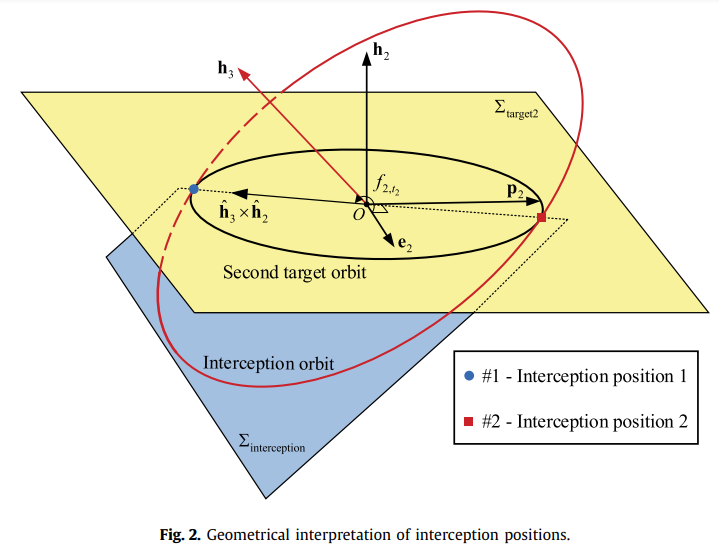

El vector $\textbf{r}_{0, {t_0}}$ sólo depende de el tiempo de impulso $t_0$, ya que al tener los parámetros de las órbitas en la tabla 1, podemos propagar la posición inicial de la NP $\textbf{r}_{0, {t_i}}$ hasta el tiempo $t_0$. Del mismo modo, $\textbf{r}_{1, {t_1}}$ sólo depende del tiempo $t_1$.

Como el plano de intercepción se determina con los vectores, y los vectores sólo dependen de los tiempos $t_0$ y $t_1$, el plano depende de los tiempos por transitividad.

**b) Calcular los vectores de posición **$\textbf{r}_{j, {t_k}}$** y velocidad **$\textbf{v}_{j, {t_k}}$

Para determinar los planos, queremos calcular los vectores de posición en la órbita $j$ y posición $t_k$ en la anomalía verdadera $f_{j, {t_k}}$. La anomalía verdadera es la posición angular de un objeto en una órbita Kepleriana.

Dicho esto, el vector $\textbf{r}_{j, {t_k}}$ en la anomalía verdadera $f_{j, {t_k}}$ es:

- $\textbf{r}_{j, {t_k}} = r_{j, {t_k}} * \Gamma_{j, {t_k}}$, donde:

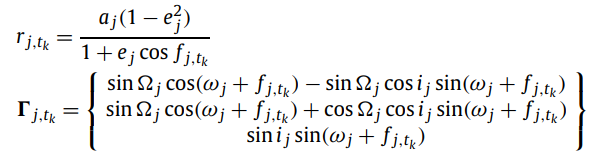

- $a_j$ es el semieje mayor

- $e_j$ es la excentricidad

- $i_j$ es la inclinación

- $\Omega$ es la longitud del nodo ascendente

- $\omega$ es el argumento de perigeo

- $f$ es la anomalía verdadera

El cálculo de estos vectores, dados los parámetros necesarios, se encuentra encapsulado en la función **r_vector** al final del archivo.

% vectores de posicion en ti
r_0_ti = r_vector(s0.a, s0.e, s0.i, s0.Omega, s0.omega, s0.f)
r_1_ti = r_vector(s1.a, s1.e, s1.i, s1.Omega, s1.omega, s1.f)

Para hallar el resto de vectores de posición, debemos hallar las anomalías verdaderas para cada vector que se necesite, ya que la tabla sólo nos proporciona la anomalía verdadera en el tiempo inicial.

**b) Paso intermedio: Cálculo de anomalías verdaderas**

Queremos hallar $\textbf{r}_{0, {t_0}}$ y $\textbf{r}_{1, {t_1}}$, pero no tenemos $f_{t_0}$ o $f_{t_1}$. Para ello, calcularemos estas anomalías verdaderas de forma numérica.

La relación entre la anomalía verdadera y la anomalía excéntrica es la siguiente:

- $tan \frac{f(t_i)}{2} = \sqrt{\frac{1 + e}{1-e}} tan \frac{E(t_i)}{2}$......(1)

Al despejar E, tenemos la formula a continuación:

- $E(t_i) = 2\cdot arctan(\sqrt{\frac{1-e}{1+e}} \cdot tan(\frac{f(t_i)}{2}))$......(2)

[*https://en.wikipedia.org/wiki/Eccentric_anomaly*](https://en.wikipedia.org/wiki/Eccentric_anomaly)

E_0_ti = 2 * atan( sqrt((1 - s0.e) / (1 + s0.e)) * tan(s0.f / 2) )

r_0_ti = 1.0e+03 *

   -7.1878
   -2.8037
    2.0193


E_1_ti = 2 * atan( sqrt((1 - s1.e) / (1 + s1.e)) * tan(s1.f / 2) )

r_1_ti = 1.0e+03 *

   -6.5986
   -4.4541
   -0.9666


Luego, utilizando la ecuación de Kepler, tenemos la relación entre la anomalía media y la anomalía excéntrica:

- $M(t_i) = E(t_i) - e \cdot sin(E(t_i))$......(3)

M_0_ti = E_0_ti - s0.e * sin(E_0_ti)

E_0_ti = 2.8247

M_1_ti = E_1_ti - s1.e * sin(E_1_ti)

E_1_ti = 2.5032

Además, por la tercera ley de Kepler:

- 
$$n = \sqrt{\frac{\mu}{a^3}}$$


n_0 = sqrt(earth_mu / s0.a^3)

M_0_ti = 2.8040

n_1 = sqrt(earth_mu / s1.a^3)

M_1_ti = 2.5106

Después, para propagar la anomalía media de $M_{t_i}$ hacia algún otro $t_k$:

- $M(t_k) = M(t_i) + n \cdot (t_k - t_i)$......(4)

% para entonces, deberíamos tener un valor semilla para t0 y t1. Como aún
% no analizamos el Porkchop Plot, usaremos valores de prueba


n_0 = 9.7202e-04

t0 = 5000

n_1 = 8.6605e-04

t1 = 25630
% tiempo de impulso, tiempo de intercepcion con el objeto 1, en segundos

M_t0 = M_0_ti + n_0 * (t0 - ti)
M_t1 = M_1_ti + n_1 * (t1 - ti)

Ahora, utilizando de nuevo la ecuación de Kepler (4):

- 
$$M(t_k) = M(t_i) + n \cdot (t_k - t_i) = E(t_k) - e \cdot sin(E(t_k))$$


- 
$$M(t_k) = E(t_k) - e \cdot sin(E(t_k))$$


Sin embargo, no podemos hallar $M(t_k)$ de forma algebráica, por lo que recurrimos a los métodos numéricos. Podemos utilizar el método de Newton Raphson. Para ello, implementamos la función **kepler_newton**, ubicada al final del archivo. Con esta función, hallamos la anomalía excéntrica en t0 y t1.

tol = 1e-8 % tolerancia utilizada para el metodo de newton intermedio

t0 = 5000

E_t0 = kepler_newton(M_t0, s0.e, tol)

t1 = 25630

E_t1 = kepler_newton(M_t1, s1.e, tol)

Finalmente, utilizando la relación entre la anomalía verdadera y la excéntrica (ecuación 1), obtenemos las anomalías verdaderas:

f_0_t0 = 2 * atan2( sqrt(1 + s0.e) * sin(E_t0 / 2), sqrt(1 - s0.e) * cos(E_t0 / 2) )

M_t0 = 7.6641

f_1_t1 = 2 * atan2( sqrt(1 + s1.e) * sin(E_t1 / 2), sqrt(1 - s1.e) * cos(E_t1 / 2) )

M_t1 = 24.7074

Y con las anomalías verdaderas, podemos calcular los verdaderos vectores de posición:

r_0_t0 = r_vector(s0.a, s0.e, s0.i, s0.Omega, s0.omega, f_0_t0)

tol = 1.0000e-08

r_1_t1 = r_vector(s1.a, s1.e, s1.i, s1.Omega, s1.omega, f_1_t1)

E_t0 = 7.7302

Una vez calculados los vectores de posición $\textbf{r}_{0, {t_0}}$ y $\textbf{r}_{1, {t_1}}$, podemos calcular la normal del plano al que pertecen (el plano orbital de intersección).

h_3 = cross(r_0_t0, r_1_t1) / norm(cross(r_0_t0, r_1_t1))

E_t1 = 24.7124

**c) Calcular las posiciones de intercepción (anomalías verdaderas)**

Tenemos el plano de intercepción con el objeto 1, y queremos hallar la línea de intercepción del plano 1 con el plano orbital de $S_2$.

- $\textbf{\hat{h}}_2$ = vector de momentum angular de la órbita de $S_2$, normalizado

Entonces, dado que el producto cruz $\vec{u} \times \vec{v} $ resulta en un vector perpendicular:

- $\textbf{\hat{h}}_3 \times \textbf{\hat{h}}_2$ = Línea de intercepción entre plano orbital de intercepcion 1 y el plano orbital del objeto $S_2$

**Punto clave: **$\textbf{r}_{2_{t_2}}$ **se encuentra en algún punto de esta línea de intercepción.**

Luego, la anomalía verdadera (es decir, la posición como ángulo) de $\textbf{\hat{h}}_3 \times \textbf{\hat{h}}_2$ se define como el ángulo entre el vector de excentricidad $\textbf{\hat{e}}_2$ hacia $\textbf{\hat{h}}_3 \times \textbf{\hat{h}}_2$. Para ello, sabemos que:

- 
$$cos(\theta) = \frac{\vec{u} \times \vec{v}}{||\vec{u}|| \cdot ||\vec{v}||}$$


Por lo que:

- 
$$cos(f_{2,{t_2}}) = \frac{(\hat{\textbf{h}}_3 \times \hat{\textbf{h}}_2) \cdot \hat{\textbf{e}_2}}{||\hat{\textbf{h}}_3 \times \hat{\textbf{h}}_2||}$$


Esta posición se puede observar como el punto azul en la figura 2.

Sin embargo, debemos hallar el vector de excentricidad $\textbf{\hat{e}}_2$. Para ello, necesitamos obtener los vectores de velocidad.

El vector de excentricidad en una órbita es:

- 
$$e = \frac{1}{\mu} [(||v||^2 - \frac{\mu}{||r||}) \cdot r - (r \cdot v)v]$$


Como podemos observar, necesitamos el vector r, que sería el vector de posición en un tiempo k, y el vector de velocidad. Podemos calcular el vector de velocidad con la función v_vector.

r_2_ti = r_vector(s2.a, s2.e, s2.i, s2.Omega, s2.omega, s2.f)

f_0_t0 = -4.7697

v_2_ti = v_vector(s2.a, s2.e, s2.i, s2.Omega, s2.omega, s2.f)

f_1_t1 = -0.4153


h_2 = cross(r_2_ti, v_2_ti) / norm(cross(r_2_ti, v_2_ti))

r_0_t0 = 1.0e+03 *

   -1.4878
    3.4285
    6.4312


r_1_t1 = 1.0e+03 *

    5.8730
    5.1012
    2.5656


e_2 = (1 / earth_mu) * ( (norm(v_2_ti)^2 - earth_mu / norm(r_2_ti)) * r_2_ti - dot(r_2_ti, v_2_ti) * v_2_ti )

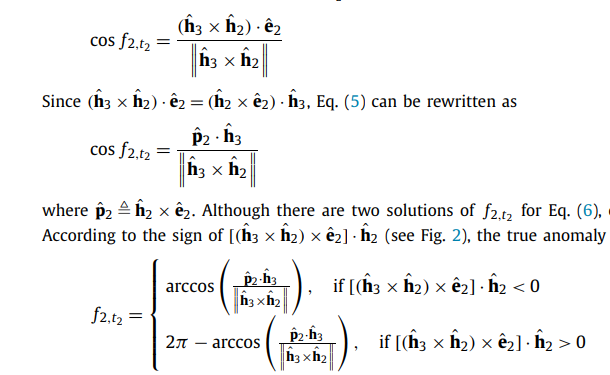

Luego, siguiendo las ecuaciones:

cos_f2_t2 = dot(cross(h_3, h_2), e_2) / norm(cross(h_3, h_2))

h_3 =    -0.4330
    0.7500
   -0.5000


dot(cross(cross(h_3, h_2), e_2), h_2) % es negativo, por lo que asignamos la opcion 1
f_2_t2 = acos(cos_f2_t2)

function r_vec = r_vector(a, e, i, Omega, omega, f)

r_2_ti = 1.0e+03 *

   -7.2350
   -5.6428
   -2.5757


    r = a * (1 - e^2) / (1 + e * cos(f));

v_2_ti =     3.1392
   -1.6749
   -5.3884


    omega_f = omega + f;


h_2 =     0.4240
   -0.7650
    0.4848


    gamma = [cos(Omega)*cos(omega_f) - sin(Omega)*cos(i)*sin(omega_f);
            sin(Omega)*cos(omega_f) + cos(Omega)*cos(i)*sin(omega_f);

e_2 =    -0.0025
    0.0045
    0.0092


            sin(i)*sin(omega_f)]; % ecuacion 3 en el paper de Xia et al.

    r_vec = r * gamma;

cos_f2_t2 = 0.0069

end

ans = -1.8438e-04

f_2_t2 = 1.5639

% honestamente no entendi por completo la logica detras de estos cálculos,
% obtuve las conversiones de perifocal a ecuatorial de wikipedia :(
% https://en.wikipedia.org/wiki/Perifocal_coordinate_system
function v_vec = v_vector(a, e, i, Omega, omega, f)
    earth_mu = 398600.4418;
    p = a * (1 - e^2);

    v_pf = sqrt(earth_mu / p) * [-sin(f); e + cos(f); 0];

    cos_O = cos(Omega); sin_O = sin(Omega);
    cos_i = cos(i);     sin_i = sin(i);
    cos_w = cos(omega); sin_w = sin(omega);

    R = [ cos_O*cos_w - sin_O*sin_w*cos_i, -cos_O*sin_w - sin_O*cos_w*cos_i, sin_O*sin_i;
          sin_O*cos_w + cos_O*sin_w*cos_i, -sin_O*sin_w + cos_O*cos_w*cos_i, -cos_O*sin_i;
          sin_w*sin_i,                     cos_w*sin_i,                      cos_i ];

    v_vec = R * v_pf;
end


function E = kepler_newton(M, e, tol)
    x0 = M;
    er = 1;
    while er > tol
        f = (x0 - e * sin(x0) - M); % f(x)
        df = (1 - e * cos(x0)); % f'(x)
        x1 = x0 - f/df;
        er = abs(x1 - x0) / abs(x1);
        x0 = x1;
    end
    E = x1; % resultado final
end